## **初始化 清除内存**

clear
clc
close all

## 参数设置

step = 1;    % 步长
eta = 0.95;  % 缩短步长比值
c = 5;  % 步长比值
n = 100; % 迭代次数
k = 20; %数组维度


## 构建数组

x = rands(k,1);
xbest = x;
fbest = f(x);
originStore = f(x);
fbestStore = fbest;

## 遍历部分

for i = 1:n
    d0 = step/c;
    dir = rands(k,1);
    dir = dir / norm(dir);
    xl = x + d0 * dir / 2;
    xr = x - d0 * dir / 2;
    fl = f(xl);
    fr = f(xr);
    x = x - step * dir * sign(fl - fr);
    temp = f(x);
    if (temp < fbest)
        fbest = temp;
    end
    originStore = [originStore ; temp];
    fbestStore = [fbestStore ; fbest];
    step = step * eta;
end



## 画图

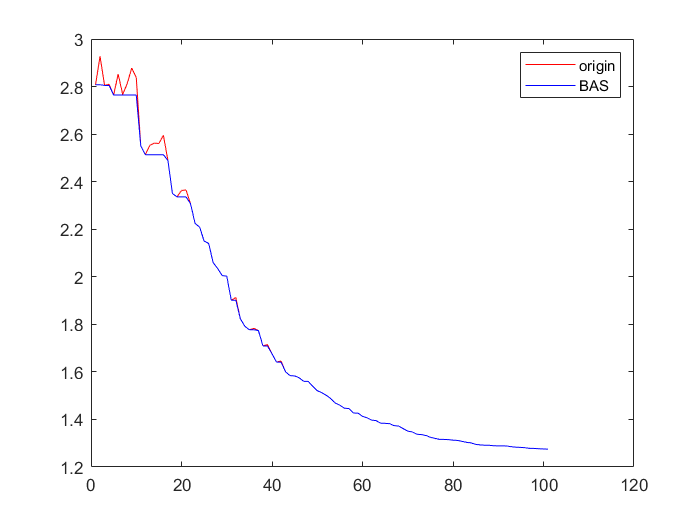

plot(1:101,originStore,"Color",'r');
hold on
plot(1:101,fbestStore,"Color",'b');
legend('origin','BAS')

function y = f(x)
y = norm(x);
end